# Optimizing Hyperparameters

This Live Script accompanies the Optimizing Hyperparameters screencast.  It follows the workflow of that video, but uses a function generated from the Regression Learner App rather than an exported model.  This function, optimizingHyperparametersModel, is included in the course files.  

## Import the Data

The May dataset was used in the "Optimizing Hyperparmeteres" screencast.  The data is read in without the data cleaning developed earlier.  After the training and test data are separated, each set will be cleaned before use.  Setting the random number generation seed (`rng`) allows for repeatability.

taxiData = importTaxiDataWithoutCleaning("yellow_tripdata_2015-05.csv"); 
rng(1);

## Partition into Training and Testing Sets

Reserve 20% of the data set for testing.

taxiPartitions = cvpartition(height(taxiData),"HoldOut",0.2);
taxiTest = taxiData(taxiPartitions.test,:);
taxiTrain = taxiData(taxiPartitions.training,:); 

## Clean the Training Data and Add Features

Here, the basic cleaning steps from Module 1 are performed on the training data.  Two predictor features, TimeOfDay and DayOfWeek, are added.

taxiTrain = basicPreprocessing(taxiTrain);
taxiTrain = addTimeOfDay(taxiTrain);
taxiTrain = addDayOfWeek(taxiTrain); 

These are the predictors used in the screencast.  This variable is not required, as the information was captured by the app and included in the generated function.

taxiPredictors = ["Distance", "PickupLat", "PickupLon", "DropoffLat", "DropoffLon", "TimeOfDay", "DayOfWeek"];

## Train an Optimized Model

This function was generated by the Regression Learner App.  It uses 20% of the training data for holdout validation.  It returns the trained model and the RMSE of the trained model applied to the validation data.

[trainedModel, validationRMSE] = optimizingHyperparametersModel(taxiTrain)

trainedModel = struct with fields:
            predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'DayOfWeek'  'Distance'  'DropoffLat'  'DropoffLon'  'PickupLat'  'PickupLon'  'TimeOfDay'}
    RegressionEnsemble: [1×1 classreg.learning.regr.RegressionBaggedEnsemble]
                 About: 'This struct is a trained model exported from Regression Learner R2020a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 4.8783

## Clean the Test Data and Add Features

The test data should be processed using the same steps as the training data.

taxiTest = basicPreprocessing(taxiTest);
taxiTest = addTimeOfDay(taxiTest);
taxiTest = addDayOfWeek(taxiTest);

## Use the Trained Model to Predict Durations for the Test Data

Now the trained model can be applied to the test data to make predictions.

yActual = taxiTest.Duration;
yPredicted = trainedModel.predictFcn(taxiTest);

## Analyze the Test Data Predictions

The metrics Mean Absolute Error, Mean Square Error, Root Mean Square Error, and the R-squared value are used to assess the performance of the model.  The residuals are calculated for later visualizations.

residuals = yActual - yPredicted;

testMetrics = rMetrics(yActual, yPredicted)

testMetrics = 1×4 table
     mae      mse       rmse       Rsq  
    _____    ______    ______    _______

    3.084    24.697    4.9696    0.81529


## Visualizations

### Response Plot

This reproduces the response plot from the App.

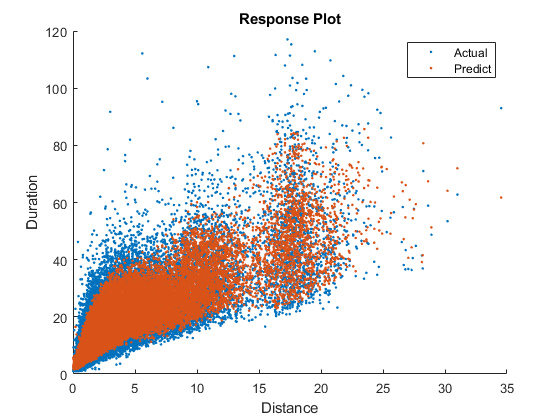

scatter(taxiTest.Distance, yActual, ".")
hold on
scatter(taxiTest.Distance, yPredicted, ".")
hold off
legend("Actual", "Predict")
xlabel("Distance (mi.)")
ylabel("Duration (min.)")
title("Response Plot")

### Residuals Plot

This two-dimensional histogram shows the distribution of the prediction error.

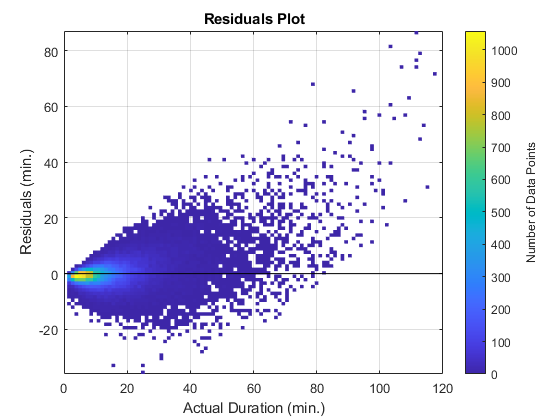

histogram2(yActual, residuals, 100, "DisplayStyle","tile")
line([0 120], [0 0], "Color", "k")
xlabel("Actual Duration (min.)")
ylabel("Residuals (min.)")
title("Residuals Plot")
cb = colorbar();
cb.Label.String = "Number of Data Points";